# Ecuaciones de diferencias

## Método de Euler implícito

Debemos despejar y hacer múltiples cosas, para discretizar la ecuación, quedando de la forma


$$y_{i+1} = y_i + \varphi h$$


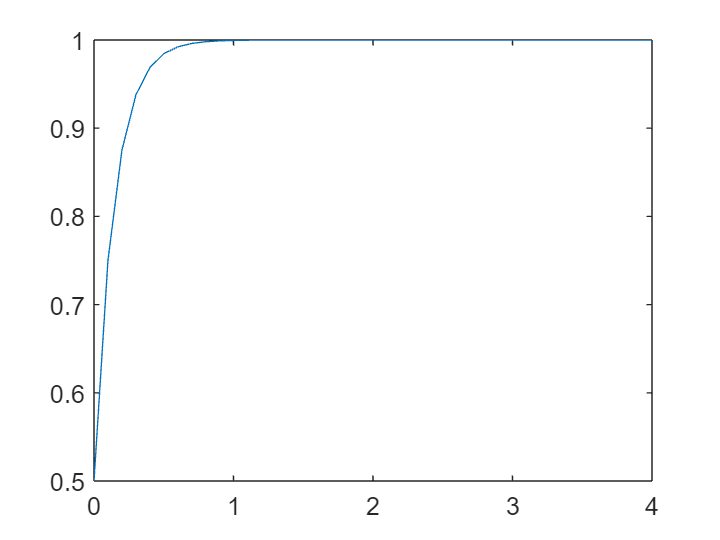

f = @(t, y) (y + 10*h)/(10*h + 1);

h = 0.1;
tspan = [0 4];
y0 = 0.5;

[t, y] = odeEulerImplicito(f, y0, tspan, h);
plot(t, y)

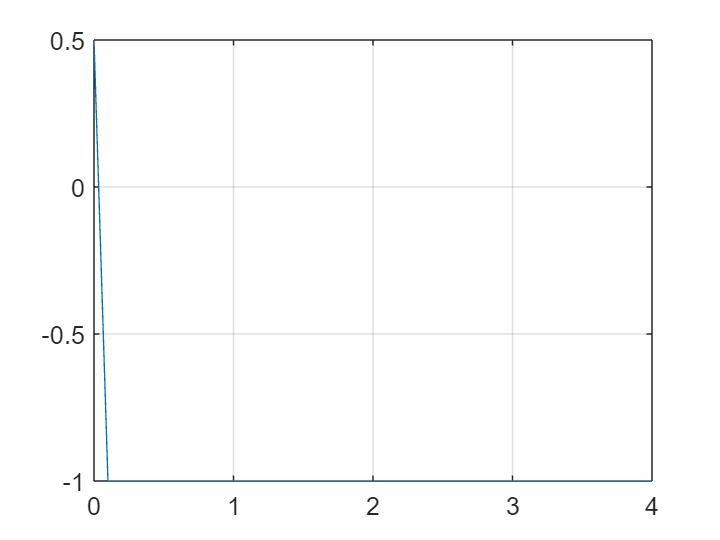

hold on
[t, y] = odeEulerImplicitoNL(f, y0, tspan, h, h);
plot(t, y)
grid on
hold off